# Metody optymalizacji - moduł 10

# Zadanie 2

### Nina Łabęcka 311339 grupa czwartek 14:15

### Dominika Pacek 311378 grupa czwartek 18:15

clc
clear

Definicje 

A = [
        0.4873  -0.8732;
        0.6072   0.7946;
        0.9880  -0.1546;
       -0.2142  -0.9768;
       -0.9871  -0.1601;
        0.9124   0.4093;
    ];
b = ones(6,1);

x_0 = [0; 0];
c = [-0.5; 0.5];
t_init = 1;
gamma = 2.5;
tolerance = 1e-6;

Rozwiązanie

[x_opt, t_final, n, hist] = SBM(A, b, c, t_init, gamma, tolerance, x_0);
x_opt

x_opt =     0.8978
   -0.6276


Generacja wykresów

limits = [-2.5 2 -1.5 3];
x1_range = linspace(limits(1), limits(2), 400);
x2_range = linspace(limits(3), limits(4), 400);
[X1, X2] = meshgrid(x1_range, x2_range);


Wykres wielokomórki

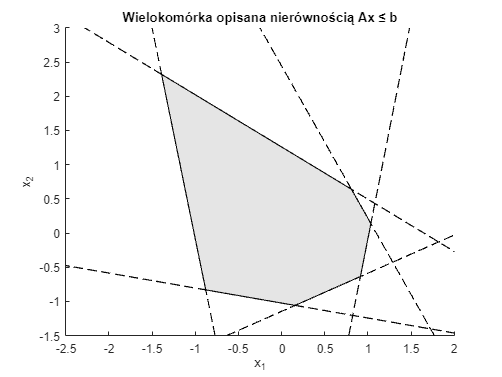

figure;
hold on;
title('Wielokomórka opisana nierównością Ax ≤ b');
xlabel('x_1');
ylabel('x_2');

for i = 1:length(A)
    intersection = (b(i) - A(i,2)*x2_range) / A(i,1);
    plot(intersection, x2_range, 'k--', 'LineWidth', 1);
end

% Wierzchołki wielokomórki
V = [0.1562 0.9127 1.0338 0.8086 -1.3895 -0.8782;
    -1.0580 -0.6358 0.1386 0.6406 2.3203 -0.8311];
k = convhull(V(1,:),V(2,:));
fill(V(1,k),V(2,k),[0.8 0.8 0.8],'EdgeColor','k');
alpha(0.5);

axis(limits);
hold off;

Wykres obszaru dopuszczalnego

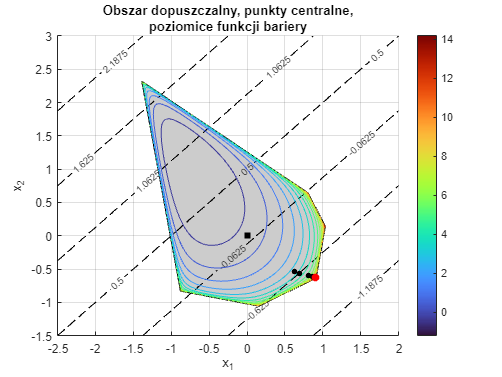

figure;
hold on;
title({'Obszar dopuszczalny, punkty centralne,', ...
        'poziomice funkcji bariery'});

fill(V(1,k),V(2,k),[0.8 0.8 0.8],'EdgeColor','k');

% poziomice funkcji celu
[C, h] = contour(X1, X2, c(1)*X1 + c(2)*X2, 7, 'k--', 'LineWidth', 1);
clabel(C, h, 'FontSize', 8);


% funkcja bariery
barrier_fun = @(x1, x2) -sum(log(b - A * [x1; x2]));

Z = zeros(size(X1));
for i = 1:numel(X1)
    if all(A * [X1(i); X2(i)] < b)
        Z(i) = barrier_fun(X1(i), X2(i));
    else
        Z(i) = NaN;  % pomijanie punktów spoza obszaru dopuszczalnego
    end
end

% poziomice funkcji bariery
contour(X1, X2, Z, 20);
colorbar;
colormap turbo;

% kolejne minima
for i = 1:n
    plot(hist(1,i), hist(2,i), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 4);
end

% punkt startowy
plot(x_0(1), x_0(2), 'ks', 'MarkerFaceColor', 'k', 'MarkerSize', );

% rozwiązanie
plot(x_opt(1), x_opt(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);


xlabel('x_1');
ylabel('x_2');
axis(limits);
grid on;
hold off;

Sekwencyjna metoda bariery

function [x_opt, t, k, hist] = SBM(A, b, c, t_init, gamma, eps, x_0)
    k = 0;
    t = t_init;
    m = size(A, 1);
    
    hist = [];
    
    fun = @(x, t) c'*x - (1/t)*sum(log(b - A*x));
    
    while m/t > eps
        
        % logarithmic barrier functions
        gradLB = @(x) -A' * (1./(b - A*x));
        hessLB = @(x) (diag(1./(b-A*x))*A)'*(diag(1./(b-A*x))*A);

        
        [x_k, ~] = NewtonDamping(x_0, eps, 0.01, 0.5, @(x) fun(x, t), gradLB, hessLB);
        
        hist = [hist x_k];
        
        t = gamma * t;
        x_0 = x_k;
        k = k + 1;
    end
    
    x_opt = x_k;
end

Metoda Newtona z tłumieniem

function [xopt, iter] = NewtonDamping(x0, eps, alfa, beta, fun, gradf, hesf)
    x = x0;
    iter = 0;
    
    while true
        g = gradf(x);
        h = hesf(x);
        
        H_reg = h + eps * eye(length(x));
        
        delta = -H_reg\g;
        
        s = 1;
        while fun(x + s*delta) > fun(x) + alfa*s*g'*delta
            s = beta*s;
        end
        
        x_new = x + s*delta;
        
        % end the search when the changes are too small
        if norm(x_new - x) < eps
            break;
        end
        
        x = x_new;
        iter = iter + 1;
    end
    
    xopt = x;
end
